# Trim, Linearise and design a Control system for the ***Lagrangian*** quadcopter and **PENDULUM** model:

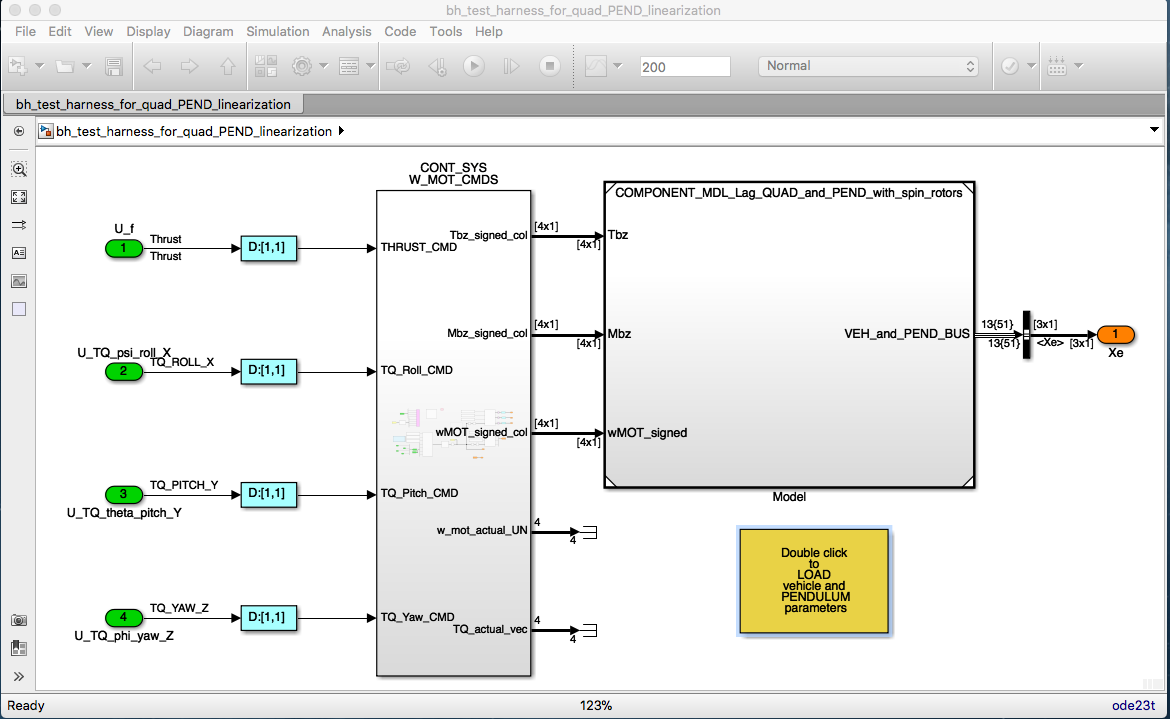

In this task we're going to linearise our **Simulink** quadcopter model. We're going to do this because we'd like to apply some "state space" control design techniques in order to design a control system for the quadcopter.  And as you know, these control techniques require a LINEAR plant model.  The workflow that we'll follow is this:

- We'll find an operating point for the pendulum. An operating point is characterized by the state(X), the input(U) and the output(Y).    We'll look specifically for an operating point that corresponds to steady state, ie: where the pendulum's state derivatives are ZERO. This is referred to as finding a **TRIMMED operating point**.

- We'll then use this TRIMMED operating point to calculate a **linearised** version of the quadcopter model.

- Finally, we'll then use this linearised model to design a full state feedback control system using the Linear Quadratic Integrator (LQI) technique.

`Bradley Horton : 18-Sept-2020, bradley.horton@mathworks.com.au  (updated for R2020b)`

# 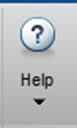 Take a moment !

If you're interested in reading about how to linearize a NON linear plant model.  Use the MATLAB HELP browser and try this simple text search

- `linearize control system`

HINT:  today we'll be using the functions:

- `operspec,   findop,   linearize`

## Load the model parameters:

bh_quad_params
bh_pend_params
bh_create_veh_and_pend_BUS

Just ensure that the the initial local Euler angles of the pendulum are ZERO:

P_pend.eul_loc_vec      = [0,0,0]'; % rad
P_veh_no_props.eul_init = [0,0,0]'; % rad

ANd echo the parameters that have been loaded into the workspace:

whos

  Name                   Size            Bytes  Class           Attributes

  PEND_BUS               1x1               311  Simulink.Bus              
  P_elec                 1x1               352  struct                    
  P_mot                  1x1              1232  struct                    
  P_mot_alone            1x1              1232  struct                    
  P_mot_vec              4x1              3584  struct                    
  P_one_prop             1x1               880  struct                    
  P_pend                 1x1               992  struct                    
  P_rot                  1x1               592  struct                    
  P_veh                  1x1              1536  struct                    
  P_veh_no_props         1x1              1536  struct                    
  VEH_AND_PEND_BUS       1x1               703  Simulink.Bus              
  XYZ_circ_mat          88x3              2112  double                    
  X_TS_OBJ              

warning('off')

## The name of the SIMULINK model that we'll linearise:

model  = 'bh_test_harness_for_quad_PEND_linearization';
open_system(model)

## Create the operating point specification object.

opspec = operspec(model);

Evaluating callback 'PostLoadFcn' for simulink
Callback: setsysloc_simulink(bdroot)
Evaluating MaskInitialization for 'bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant': 'blkName = gcb;  if strcmp(get_param(gcbh,'OutDataTypeStr'),'boolean') 	setValue = 'boolean'; else 	s...'.
Evaluating callback 'MaskParameterCallback' for bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant
Callback: sl('zeroCrossEnable', gcbh);
Evaluating MaskInitialization for 'bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant': 'blkName = gcb;  if strcmp(get_param(gcbh,'OutDataTypeStr'),'boolean') 	setValue = 'boolean'; else 	s...'.
Evaluating MaskInitialization for 'COMPONENT_MDL_Lag_QUAD_and_PEND_with_spin_rotors/bh_6DOF_and_pend': ' '.


In our operating point specification, note the following:

- Our GREEN root level INPORT blocks are the system inputs 

- Our ORANGE root level OUTPORT blocks are the system outputs 

display(opspec)

opspec =  Operating point specification for the Model bh_test_harness_for_quad_PEND_linearization.
 (Time-Varying Components Evaluated at time t=0)

States: 
----------
    x    Known    SteadyState    Min     Max    dxMin    dxMax
    _    _____    ___________    ____    ___    _____    _____

(1.) DOT_phi
    0    false       true        -Inf    Inf    -Inf      Inf 
(2.) 

For each of our model states we can specify "desired" values for each of the following.  

- `x           :`   initial guess for state value

- `SteadyState :`   a logical indicating we are looking for a dx=0 final value

- `Min         :`   minimum bound for state value

- `Max         :`   maximum bound for state value

For our problem, we're going to look for an operating point where ALL of our states are at SteadyState (ie: dx/dt=0)

%[ opspec.States(1).SteadyState]
%[ arrayfun(@(a) (a.SteadyState), opspec.States) ].'

Our trimming function(coming up next) will then look for an operating point that satisfies this specification:

## Look for the steady state operating point.

opt           = findopOptions('DisplayReport','off');
[op,opreport] = findop(model,opspec, opt);

Evaluating callback 'MaskParameterCallback' for bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant
Callback: sl('zeroCrossEnable', gcbh);
Evaluating MaskInitialization for 'bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant': 'blkName = gcb;  if strcmp(get_param(gcbh,'OutDataTypeStr'),'boolean') 	setValue = 'boolean'; else 	s...'.
Evaluating MaskInitialization for 'COMPONENT_MDL_Lag_QUAD_and_PEND_with_spin_rotors/bh_6DOF_and_pend': ' '.


Review our trimmed OPERATING point and NOTE the following:

- We have indeed found a steady state operating point because the state derivatives are either zero OR very small $O(10^{-7})$

- In this trimmed pose, ALL of the system outputs are ZERO.

- To maintain this trimmed pose we need to supply an INPUT force ... which is the force to counter gravity. 

display(opreport)

opreport =  Operating point search report for the Model bh_test_harness_for_quad_PEND_linearization.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
    Min               x              Max    dxMin             dx              dxMax
    ____    _____________________    ___    _____    _____________________    _____

(1.) DOT_phi
    -Inf                        0    Inf      0      -7.84584374501767e-29      0  
(2.) 

## Linearize the model about this operating point:

Next we'll linearise our model about this trimmed operating point:

my_LIN_PLANT = linearize(model,op);

Evaluating callback 'MaskParameterCallback' for bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant
Callback: sl('zeroCrossEnable', gcbh);
Evaluating MaskInitialization for 'bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant': 'blkName = gcb;  if strcmp(get_param(gcbh,'OutDataTypeStr'),'boolean') 	setValue = 'boolean'; else 	s...'.
Evaluating MaskInitialization for 'COMPONENT_MDL_Lag_QUAD_and_PEND_with_spin_rotors/bh_6DOF_and_pend': ' '.


Note the names of the **INPUTS** "U"  

my_LIN_PLANT.InputName

ans = 4×1 cell array
    {'U_f'               }
    {'U_TQ_psi_roll_X'   }
    {'U_TQ_theta_pitch_Y'}
    {'U_TQ_phi_yaw_Z'    }


and the **OUTPUTS** "Y" 

my_LIN_PLANT.OutputName

ans = 3×1 cell array
    {'bh_test_harness_for_quad_PEND_linearization/Xe(1,1)'}
    {'bh_test_harness_for_quad_PEND_linearization/Xe(2,1)'}
    {'bh_test_harness_for_quad_PEND_linearization/Xe(3,1)'}


and the **STATES** "X"

my_LIN_PLANT.StateName

ans = 18×1 cell array
    {'DOT_phi'       }
    {'DOT_theta'     }
    {'DOT_psi'       }
    {'DOT_Xe'        }
    {'DOT_Ye'        }
    {'DOT_Ze'        }
    {'DOT_phi_pend'  }
    {'DOT_theta_pend'}
    {'DOT_psi_pend'  }
    {'phi'           }
    {'theta'         }
    {'psi'           }
    {'Xe'            }
    {'Ye'            }
    {'Ze'            }
    {'phi_pend'      }
    {'theta_pend'    }
    {'psi_pend'      }


Check if the linearised system is Full state Feedback(FSFB) Controllable. If the system is NOT FSFB controllable it means that we can NOT ***arbitrarily position*** the system poles.  We may still be able to position them to obtain a stable system  ... it's just that we can't arbitrarily position them.

A = my_LIN_PLANT.A;
B = my_LIN_PLANT.B;
C = my_LIN_PLANT.C;
D = my_LIN_PLANT.D;

co = ctrb(A,B);
% if(rank(co) ~= size(A,1) )
%     error('###_ERROR: the system is NOT FSFB controllable');
% end

And close the model:

close_system(model)

## Control design:

We'll use the approach described by the LQI() function, ie::

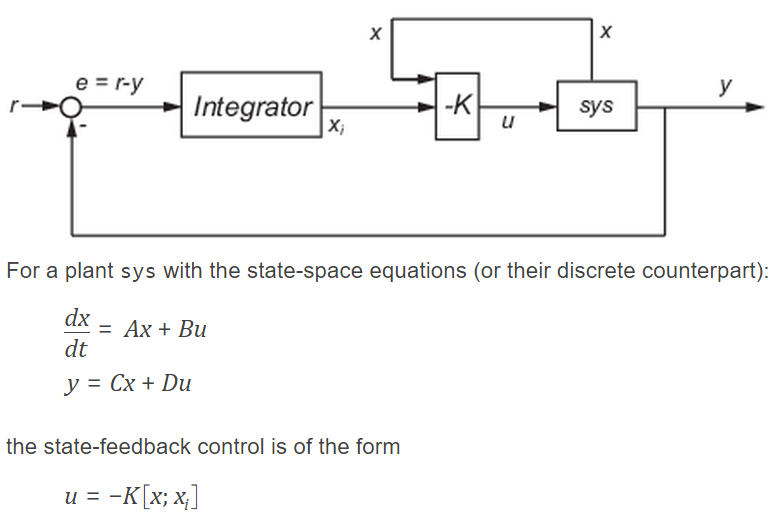

Note that:  

- 
$$K\in R^{N_u \times \left(N_x +N_y \right)}$$


Nx = size(A,1);  Nu = size(B,2);  Ny = size(C,1);

Now design a full state feedback controller using `LQI()`. NOTE the following:

- you will need to experiment with the Q,R weighting matrices

:   **TODO**

- perform a model reduction step before doing the control design

- develop an observer to supply the new states for the design

[Q,R]   = LOC_calc_Q_and_R(Nx, Ny);

[K,~,~] = lqi(my_LIN_PLANT,Q,R,[])

K =     0.0866    0.0000    0.0000    0.0000   -0.0000    1.1703    0.0866    0.0000    0.0000    0.0007    0.0000    0.0000    0.0000   -0.0000    0.5817    0.0007    0.0000    0.0000   -0.0000   -0.0000   -0.1446
    0.0028   -0.0000   -0.0932   -0.0000    0.0216    0.0000    0.0028   -0.0000   -0.2033    0.0002   -0.0000   -0.1739   -0.0000    0.0155    0.0000    0.0002   -0.0000   -1.2788    0.0000   -0.0053   -0.0000
   -0.0192   -0.0932    0.0000   -0.0216   -0.0000   -0.0000   -0.0192   -0.2033    0.0000   -0.0002   -0.1739    0.0000   -0.0155   -0.0000   -0.0000   -0.0002   -1.2788    0.0000    0.0053   -0.0000    0.0000
   -0.0016    0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0147    0.0000    0.0000    0.0016    0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0037    0.0000    0.0000   -0.0000   -0.0000    0.0001


What does the gain matrix K, look like?

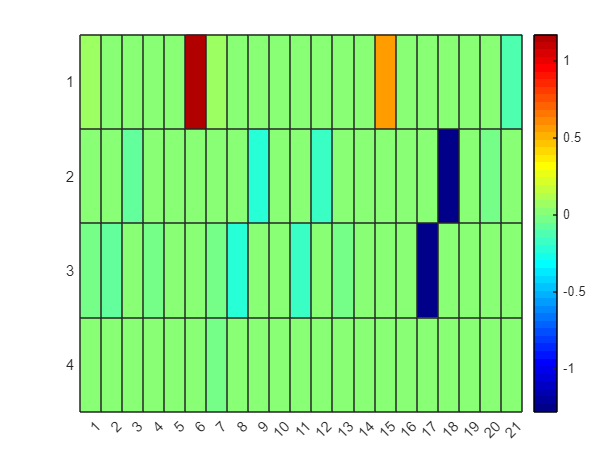

hfig = figure;
   heatmap(K,'Colormap', jet(50) );

What do the closed loop poles look like ?

A_hat = [  A,   zeros(Nx,Ny);
          -C,   zeros(Ny,Ny) ];
      
B_hat = [ B;
          zeros(Ny,Nu) ];
p_lqi = esort( pole( ss((A_hat-B_hat*K),[],[],[]) ) )

p_lqi =   -0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.2485 + 0.4305i
  -0.2485 - 0.4305i
  -0.4798 + 0.3947i
  -0.4798 - 0.3947i
  -0.4971 + 0.0000i
  -0.7231 + 1.4449i
  -0.7231 - 1.4449i
  -0.7231 + 1.4449i


Now test the design using ONLY the linearised plant:

x0 = zeros((Nx),1);
%open_system('bh_test_harness_check_linear_control_law')

Now save the results:

RESULTS_FILE_NAME = 'bh_CONT_DES_RESULTS.mat';
the_state_names =  my_LIN_PLANT.StateName;
save(RESULTS_FILE_NAME, 'K', 'the_state_names')

## Should we commit this design ?

If you want to commit this design then run the following code also:

tf_i_will_commit_design = false;
if(true==tf_i_will_commit_design)
    RESULTS_FILE_NAME = 'CONFIRMED_bh_CONT_DES_RESULTS.mat';
    the_state_names =  my_LIN_PLANT.StateName;
    save(RESULTS_FILE_NAME, 'K', 'the_state_names')
end

# Local Subfunctions only beyond this point

  **ATTENTION**

- The following SUB functions create the  `Q` and `R` matrices needed for the lqi() control design task.

- So how did I choose the weight for `Q` and `R` ? - In short a generated a collection of candidate designs and then applied these designs to my NONlinear model `bh_SM_quad_and_PEND.slx`.  I then "picked" a good one.  See the script file `bh_sweep_through_candidate_control_laws_CONTINUOUS.mlx`

:   **TODO**

- perform a model reduction step before doing the control design

- develop an observer to supply the new states for the design

function [Q,R] = LOC_calc_Q_and_R(Nx, Ny)

   THE_RELEASE = string (  version('-release')  );
   
   switch( upper(THE_RELEASE) )

       case "2021B"
                    [Q,R] = LOC_get_R2021b_Q_and_R(Nx, Ny);
       case "2021A"
                    [Q,R] = LOC_get_R2021a_Q_and_R(Nx, Ny);
       case "2020B"
                    [Q,R] = LOC_get_R2020b_Q_and_R(Nx, Ny);
       case "2020A"
                    [Q,R] = LOC_get_R2020a_Q_and_R(Nx, Ny);
       case "2019B"
                    [Q,R] = LOC_get_R2019b_Q_and_R(Nx, Ny);
       case "2018B"
                    [Q,R] = LOC_get_R2018b_Q_and_R(Nx, Ny);
       otherwise
           error("###_ERROR: Unaccounted release");
   end
       
end

: the following design was developed in **R2018b**.  In this release the LQI function utilised a CARE solver.  In 19a a new IMPLICIT solver ICARE was rolled out.  For my model the 18b design was a very good starting design and I've kept it here:

-  `CONFIRMED_bh_CONT_DES_RESULTS_PRE_19a_using_CARE_SOLVER.mat`

function [Q,R] = LOC_get_R2018b_Q_and_R(Nx, Ny)
    
    tmp        = 1*[ones(1, Nx+Ny)];
    tmp(19:21) = [2,2,1500];
    Q          = diag(tmp); 
    
    %tmp       = 3e4*[1,1,1,1];  %17b - LQI uses care()
    %tmp       = 2e4*[1,1,1,1];  %18a - LQI uses care()
    tmp        = 5e4*[1,1,1,1];  %18b
    R          = diag(tmp); 

end

:   the following design was developed in **R2019b**. 

function [Q,R] = LOC_get_R2019b_Q_and_R(Nx, Ny)

    tmp        = 1*[ones(1, Nx+Ny)];
    tmp(19:21) = [2,2,1500];
    Q          = diag(tmp); 
    
    tmp        = 73799*[1,1,1,1]; % 19b - LQI uses icare() ... NEW IMPLICIT SOLVER rolled out in 19a
    R          = diag(tmp); 

end

:   the following design was developed in **R2020a**.

function [Q,R] = LOC_get_R2020a_Q_and_R(Nx, Ny)

    tmp        = 1*[ones(1, Nx+Ny)];
    tmp(19:21) = [2,2,1500];
    Q          = diag(tmp); 
    
    tmp        = 74678*[1,1,1,1]; 
    R          = diag(tmp); 

end

:   the following design was developed in **R2020b**.

function [Q,R] = LOC_get_R2020b_Q_and_R(Nx, Ny)

    tmp        = 1*[ones(1, Nx+Ny)];
    tmp(19:21) = [2,2,1500];
    Q          = diag(tmp); 
    
    tmp        = 82196*[1,1,1,1]; 
    R          = diag(tmp); 

end

:   the following design was developed in **R2021a**.

function [Q,R] = LOC_get_R2021a_Q_and_R(Nx, Ny)

    tmp        = 1*[ones(1, Nx+Ny)];
    tmp(19:21) = [2,2,1500];
    Q          = diag(tmp); 
    
    tmp        = 89289*[1,1,1,1]; 
    R          = diag(tmp); 

end

:   the following design was developed in **R2021b**.

function [Q,R] = LOC_get_R2021b_Q_and_R(Nx, Ny)

    tmp        = 1*[ones(1, Nx+Ny)];
    tmp(19:21) = [2,2,1500];
    Q          = diag(tmp); 
    
    tmp        = 71766*[1,1,1,1]; 
    R          = diag(tmp); 

end